# Tarea: Navegación por Campo Potencial con Robot Pioneer P3DX

Autores: Andrés Sebastian Serna Montaño

Joan Pinilla

## Paso 1: Modelo cinemático del robot Pioneer P3DX

El Pioneer P3DX es un robot diferencial.

Cinemática: 


$$\frac{\textrm{dx}}{\textrm{dt}}=v*\textrm{Cos}\left(\theta \right)$$



$$\frac{\textrm{dy}}{\textrm{dt}}=v*\textrm{Sin}\left(\theta \right)$$



$$\frac{d\theta }{\textrm{dt}}=w$$


## Paso 2.1: Calcular el radio R del círculo que incluye al robot

Dimensiones aproximadas del Pioneer P3DX:

Ancho: 0.381 m

Largo: 0.455 m

Radio de inclusión R:

R = sqrt((0.381)^2 + (0.455)^2)/2;
k = 10 * R; % Factor de escala para el mapa

## Paso 2.2: Generar mapa con obstáculos usando arena2025

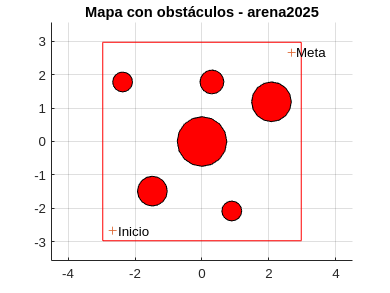

clf
figure(1); hold on
plot(k*[-1 1 1 -1 -1], k*[-1 -1 1 1 -1], 'r')
CC = k*0.1 * [3 -7;-5 -5;0 0;-8 6;1 6;7 4]; % centros de obstáculos
RC = k*0.1 * [1 1.5 2.5 1 1.2 2];          % radios de obstáculos
t = 0:pi/8:2*pi;
for i = 1:length(RC)
    patch(CC(i,1)+RC(i)*sin(t), CC(i,2)+RC(i)*cos(t), 'r')
end
plot(k*[-.9, .9], k*[-.9, .9], '+')
text(-k*.85, -k*.9, 'Inicio')
text(k*.95, k*.9, 'Meta')
axis(k*[-1.2 1.2 -1.2 1.2]); axis equal; grid on
title('Mapa con obstáculos - arena2025')


nombreMapa = 'Mapa_Pioneer296';

## Paso 2.3: Campo de repulsión con función tangente sigmoidal

% f(d) = 1 / (1 + exp(-a*(d - d0)))


## Paso 3: Navegación por Campo Potencial

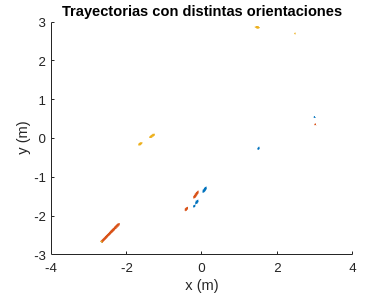

right_wheel_speeds = 1×1 cell array
    {[6.0170 5.8392 5.7291 5.5768 5.5198 5.4415 5.3461 5.3359 5.2944 5.2618 5.2351 5.2137 5.1973 5.1835 5.1724 -5.4867 -3.3637 -1.1467 0.1083 1.1123 3.2670 3.6392 2.3853 2.9339 13.8801 12.1297 10.7618 9.6351 8.7711 8.0425 7.4977 7.0238 6.6835 6.3725 6.1631 -2.3953 -0.8906 0.3133 1.2763 2.0488 2.6647 11.6297 10.3294 9.3197 8.5237 7.8446 7.3444 6.8711 6.5667 6.2790 6.0937 5.8705 5.7220 5.6493 5.5145 5.4372 5.3916 5.3389 5.2968 5.2800 5.2497 5.1929 5.1799 5.2199 5.1685 5.1604 5.1721 5.1633 5.1563 5.1160 5.1722 5.1281 5.1281 5.0917 5.1549 5.1496 5.1082 5.1699 5.1237 5.1246 5.1253 -3.5485 -1.8132 -0.2229 1.0231 1.4668 2.2005 2.7861 3.2545 -4.6852 -2.7225 -0.9937 0.2307 1.3386 2.0965 2.8015 3.2668 -0.9575 0.2237 1.1456 1.9422 2.5415 3.0589 -5.2013 -3.1354 -1.4383 0.0322 1.0514 2.0425 2.2823 2.8515 3.3083 12.5277 11.0478 14.1833 12.3723 10.1625 9.7358 8.8143 8.0771 5.1077 5.1118 -5.4996 -3.3741 0.7822 1.6514 2.3507 2.9062 9.9769 9.0071 8.3053 7.6698 7.2370 

right_wheel_speeds = 1×2 cell array
    {[6.0170 5.8392 5.7291 5.5768 5.5198 5.4415 5.3461 5.3359 5.2944 5.2618 5.2351 5.2137 5.1973 5.1835 5.1724 -5.4867 -3.3637 -1.1467 0.1083 1.1123 3.2670 3.6392 2.3853 2.9339 13.8801 12.1297 10.7618 9.6351 8.7711 8.0425 7.4977 7.0238 6.6835 6.3725 6.1631 -2.3953 -0.8906 0.3133 1.2763 2.0488 2.6647 11.6297 10.3294 9.3197 8.5237 7.8446 7.3444 6.8711 6.5667 6.2790 6.0937 5.8705 5.7220 5.6493 5.5145 5.4372 5.3916 5.3389 5.2968 5.2800 5.2497 5.1929 5.1799 5.2199 5.1685 5.1604 5.1721 5.1633 5.1563 5.1160 5.1722 5.1281 5.1281 5.0917 5.1549 5.1496 5.1082 5.1699 5.1237 5.1246 5.1253 -3.5485 -1.8132 -0.2229 1.0231 1.4668 2.2005 2.7861 3.2545 -4.6852 -2.7225 -0.9937 0.2307 1.3386 2.0965 2.8015 3.2668 -0.9575 0.2237 1.1456 1.9422 2.5415 3.0589 -5.2013 -3.1354 -1.4383 0.0322 1.0514 2.0425 2.2823 2.8515 3.3083 12.5277 11.0478 14.1833 12.3723 10.1625 9.7358 8.8143 8.0771 5.1077 5.1118 -5.4996 -3.3741 0.7822 1.6514 2.3507 2.9062 9.9769 9.0071 8.3053 7.6698 7.2370 

right_wheel_speeds = 1×3 cell array
    {[6.0170 5.8392 5.7291 5.5768 5.5198 5.4415 5.3461 5.3359 5.2944 5.2618 5.2351 5.2137 5.1973 5.1835 5.1724 -5.4867 -3.3637 -1.1467 0.1083 1.1123 3.2670 3.6392 2.3853 2.9339 13.8801 12.1297 10.7618 9.6351 8.7711 8.0425 7.4977 7.0238 6.6835 6.3725 6.1631 -2.3953 -0.8906 0.3133 1.2763 2.0488 2.6647 11.6297 10.3294 9.3197 8.5237 7.8446 7.3444 6.8711 6.5667 6.2790 6.0937 5.8705 5.7220 5.6493 5.5145 5.4372 5.3916 5.3389 5.2968 5.2800 5.2497 5.1929 5.1799 5.2199 5.1685 5.1604 5.1721 5.1633 5.1563 5.1160 5.1722 5.1281 5.1281 5.0917 5.1549 5.1496 5.1082 5.1699 5.1237 5.1246 5.1253 -3.5485 -1.8132 -0.2229 1.0231 1.4668 2.2005 2.7861 3.2545 -4.6852 -2.7225 -0.9937 0.2307 1.3386 2.0965 2.8015 3.2668 -0.9575 0.2237 1.1456 1.9422 2.5415 3.0589 -5.2013 -3.1354 -1.4383 0.0322 1.0514 2.0425 2.2823 2.8515 3.3083 12.5277 11.0478 14.1833 12.3723 10.1625 9.7358 8.8143 8.0771 5.1077 5.1118 -5.4996 -3.3741 0.7822 1.6514 2.3507 2.9062 9.9769 9.0071 8.3053 7.6698 7.2370 

% Parámetros iniciales
k_atr = 1;        % Atracción
k_rep = 100;      % Repulsión
a_sig = 10;       % Pendiente sigmoide
d0 = 0.5;         % Distancia de activación repulsión

% Puntos de inicio y meta
start = [-k*0.9; -k*0.9];
goal = [k*0.9; k*0.9];

[X, Y] = meshgrid(-k:0.1:k, -k:0.1:k);
U = zeros(size(X));

% Campo atractivo
U_atr = 0.5 * k_atr * ((X - goal(1)).^2 + (Y - goal(2)).^2);
U = U + U_atr;

% Campo repulsivo con sigmoide
for i = 1:length(RC)
    dx = X - CC(i,1);
    dy = Y - CC(i,2);
    dist = sqrt(dx.^2 + dy.^2) - RC(i);
    f_rep = k_rep * (1 - (1 ./ (1 + exp(-a_sig*(dist - d0)))));
    f_rep(dist > d0) = 0; % sin repulsión si está lejos
    U = U + f_rep;
end

% Gradiente del campo
[Fx, Fy] = gradient(-U);

%% Simulación del movimiento del robot para orientaciones 30°, 45°, 60°
orientaciones = [30, 45, 60] * pi/180;

% for j = 1:length(orientaciones)
%     x = [start; orientaciones(j)];
%     dt = 0.1;
%     x_hist = x;
%     for i = 1:300
%         % Posición actual del robot
%         px = x(1);
%         py = x(2);
% 
%         % Buscar el gradiente más cercano
%         ix = round((px + k)/0.1)+1;
%         iy = round((py + k)/0.1)+1;
%         if ix < 1 || iy < 1 || ix > size(Fx,1) || iy > size(Fx,2)
%             break;
%         end
% 
%         grad = [Fx(iy,ix); Fy(iy,ix)];
% 
%         % Dirección deseada
%         theta_d = atan2(grad(2), grad(1));
%         dtheta = wrapToPi(theta_d - x(3));
% 
%         % Control proporcional simple
%         v = 0.5;
%         w = 2*dtheta;
% 
%         % Simular movimiento
%         x = x + dt * modeloP3DX(0, x, [v; w]);
%         x_hist(:,end+1) = x;
% 
%         % Criterio de parada
%         if norm(x(1:2) - goal) < 0.2
%             break;
%         end
%     end
% 
%     % Graficar trayectoria
%     figure(3); hold on
%     plot(x_hist(1,:), x_hist(2,:), 'LineWidth', 2)
%     title('Trayectorias con distintas orientaciones')
%     xlabel('x (m)'); ylabel('y (m)');
% end
% 
% legend('30°', '45°', '60°')
% axis equal


% Parameters for the Pioneer P3DX
wheel_radius = 0.0975; % in meters
wheel_base = 0.331;    % distance between wheels in meters

% Initialize variables to store wheel speeds
left_wheel_speeds = [];
right_wheel_speeds = [];

figure(3);
clf;
hold on
title('Trayectorias con distintas orientaciones')
xlabel('x (m)'); ylabel('y (m)');

for j = 1:length(orientaciones)
    x = [start; orientaciones(j)];
    dt = 0.1;
    x_hist = x;
    wheel_speeds_j = []; % Store wheel speeds for this orientation
    
    for i = 1:300
        % Posición actual del robot
        px = x(1);
        py = x(2);
        
        % Buscar el gradiente más cercano
        ix = round((px + k)/0.1)+1;
        iy = round((py + k)/0.1)+1;
        if ix < 1 || iy < 1 || ix > size(Fx,1) || iy > size(Fx,2)
            break;
        end
        
        grad = [Fx(iy,ix); Fy(iy,ix)];
        
        % Dirección deseada
        theta_d = atan2(grad(2), grad(1));
        dtheta = wrapToPi(theta_d - x(3));

        % Control proporcional simple
        v = 0.5;
        w = 2*dtheta;
        
        % Calculate wheel speeds (in rad/s)
        v_right = (2*v + w*wheel_base)/(2*wheel_radius);
        v_left = (2*v - w*wheel_base)/(2*wheel_radius);
        
        % Store wheel speeds
        wheel_speeds_j(:,end+1) = [v_left; v_right];
        
        % Simular movimiento
        x = x + dt * modeloP3DX(0, x, [v; w]);
        x_hist(:,end+1) = x;
        
        % Criterio de parada
        if norm(x(1:2) - goal) < 0.2
            break;
        end

    end


    plot(x_hist(1,:), x_hist(2,:), 'LineWidth', 2, 'DisplayName', sprintf('%d°', orientaciones(j)*180/pi))
    
    % Store all wheel speeds for this trajectory
    left_wheel_speeds{j} = wheel_speeds_j(1,:);
    right_wheel_speeds{j} = wheel_speeds_j(2,:)
end

## Paso 3.4: Tabla de parámetros usados

fprintf('\nParametros usados:\n')


Parametros usados:


fprintf('k_atr = %.2f\n', k_atr)

k_atr = 1.00


fprintf('k_rep = %.2f\n', k_rep)

k_rep = 100.00


fprintf('a_sig = %.2f\n', a_sig)

a_sig = 10.00


fprintf('d0 = %.2f\n', d0)

d0 = 0.50


## Paso 4: Visualización del Gradiente del Campo Potencial

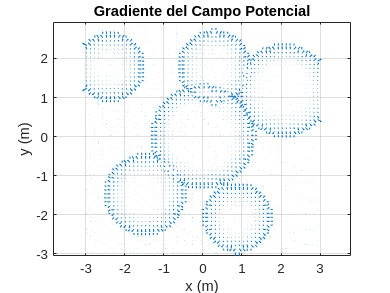

figure(4);
quiver(X, Y, Fx, Fy)
title('Gradiente del Campo Potencial')
xlabel('x (m)'); ylabel('y (m)');
axis equal; grid on

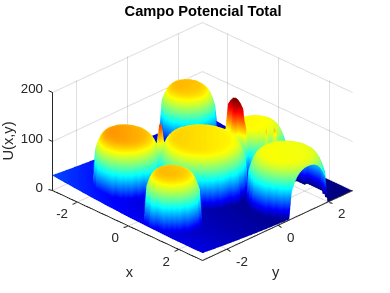


figure(5);
surf(X, Y, U);
title('Campo Potencial Total');
xlabel('x'); ylabel('y'); zlabel('U(x,y)');
shading interp; colormap jet; view(45, 45);

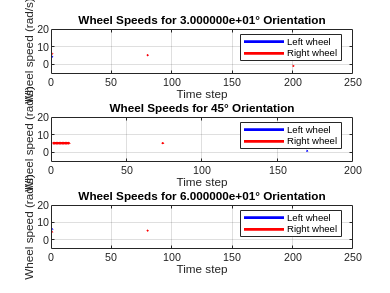




%% Plot wheel speeds for each trajectory
figure(6);
for j = 1:length(orientaciones)
    subplot(length(orientaciones),1,j);
    plot(left_wheel_speeds{j}, 'b', 'LineWidth', 2); hold on;
    plot(right_wheel_speeds{j}, 'r', 'LineWidth', 2);
    title(sprintf('Wheel Speeds for %d° Orientation', orientaciones(j)*180/pi));
    xlabel('Time step');
    ylabel('Wheel speed (rad/s)');
    legend('Left wheel', 'Right wheel');
    grid on;
end


%% Display maximum wheel speeds
fprintf('\nMaximum wheel speeds:\n');


Maximum wheel speeds:


for j = 1:length(orientaciones)
    fprintf('Orientation %d°:\n', orientaciones(j)*180/pi);
    fprintf('  Max left wheel speed: %.2f rad/s\n', max(abs(left_wheel_speeds{j})));
    fprintf('  Max right wheel speed: %.2f rad/s\n', max(abs(right_wheel_speeds{j})));
end

Orientation 3.000000e+01°:


  Max left wheel speed: 15.76 rad/s


  Max right wheel speed: 14.25 rad/s


Orientation 45°:


  Max left wheel speed: 15.79 rad/s


  Max right wheel speed: 14.41 rad/s


Orientation 6.000000e+01°:


  Max left wheel speed: 15.14 rad/s


  Max right wheel speed: 15.74 rad/s
